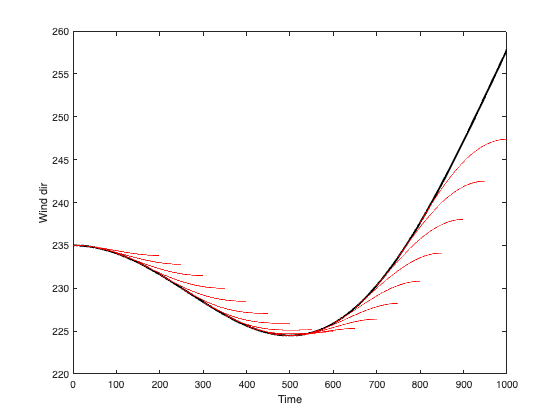

t = linspace(0,1000,1000);
phi     = 0.00003*t.^2 + 10*cos(t/200) + 225;
ph      = 200;
up      = 0:50:800;
trust   = linspace(1,0,ph);
figure
plot(t,phi,'k','LineWidth',2)
hold on
for iU = 1:length(up)
    tu = up(iU):up(iU)+ph;
    phi_relevant = interp1(t,phi,tu);
    p_diff = diff(phi_relevant) .* trust;
    phi_u = cumsum([phi_relevant(1); p_diff(:)]);
    plot(tu,phi_u,'-r')
end
xlim([0, 1000])
ylabel('Wind dir')
xlabel('Time')